# Análisis de Color

#### Lista de parámetros

- originalImage: imagen por manipular (debe estar en el modelo RGB)

- maxClusters: Número de clusters

- maxIter: número máximo de iteraciones para el algoritmo de segmentación

Las imagenes incluidas en el reporte son: 399, 402, 3 y 1185

originalImage = imread('malignant/399.jpg');
maxClusters = 15;
maxIter = 100;

#### Segmentación de color con álgoritmo K-Means

Utilizando el algoritmo K-means y aplicando el método del codo para determinar el número óptimo de clústeres, se procede a segmentar los colores de la imagen original.

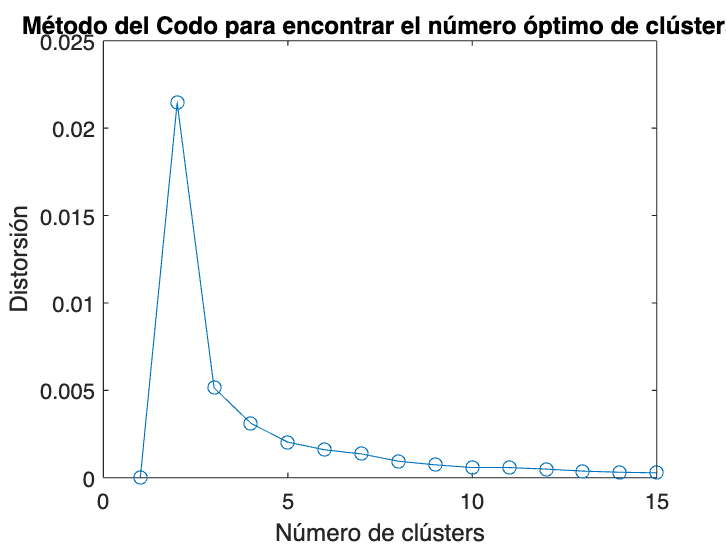

         0    0.0215    0.0051    0.0031    0.0020    0.0016    0.0014    0.0009    0.0007    0.0006    0.0006    0.0005    0.0004    0.0003    0.0003

El número óptimo de clústers es: 5.146679e-03
     5



clusterNo = floor(findOptimalCluster(originalImage, maxClusters, 100));


im2 = reshape(originalImage,[size(originalImage,1)*size(originalImage,2) 3]);
     
[pixelNo,~] = size(im2);

% De forma aleatoria, se seleccionan ''clusterNo'' índices de la matriz.
randIndices = randperm(pixelNo,clusterNo);

centers = double(im2(randIndices,:));
    
for iter=1:maxIter
    % Calcula la distancia euclidiana entre los centros y cada píxel
    D = pdist2(centers,double(im2));
    % Asignar cada píxel al cluster con la distancia mínima
    [~,min_indices] = min(D); 
     
    for j=1:clusterNo
        centers(j,:) = mean(im2(min_indices == j,:));
    end
end
    
cmap = min_indices';
cmap2 = reshape(cmap, [size(originalImage,1) size(originalImage,2)]);
    
colors = centers / 255;
segmentedImage = zeros(size(originalImage,1), size(originalImage,2), 3, 'double');

#### Visualización de imagenes segmentadas: fondo negro

Los colores obtenidos tras la segmentación se organizan en una única fila, donde cada columna representa una tonalidad única de la imagen segmentada. Se establece un fondo de color negro para las áreas que no corresponden al color separado.

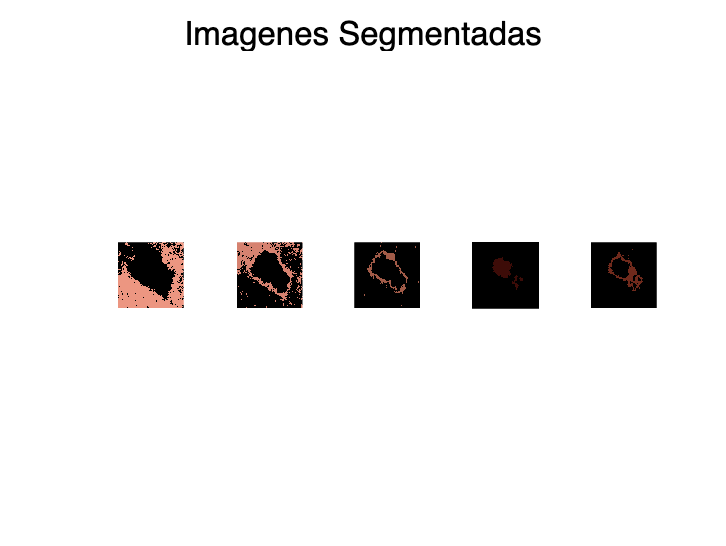

results01 = cell(1, 5);
    
for i = 1:5
    results01{i} = zeros(size(originalImage, 1), size(originalImage, 2), 3, 'double');
end

for fila = 1:size(originalImage,1)
    for columna = 1:size(originalImage,2)
        actualValue = cmap2(fila,columna);
        results01{actualValue}(fila,columna, 1) = colors(cmap2(fila,columna),1);
        results01{actualValue}(fila,columna, 2) = colors(cmap2(fila,columna),2);
        results01{actualValue}(fila,columna, 3) = colors(cmap2(fila,columna),3);
    end
end

showMultipleImagesNL('Imagenes Segmentadas',results01);

#### Visualización de imagenes segmentadas: fondo blanco

Los colores obtenidos tras la segmentación se organizan en una única fila, donde cada columna representa una tonalidad única de la imagen segmentada. Se establece un fondo de color blanco para las áreas que no corresponden al color separado.

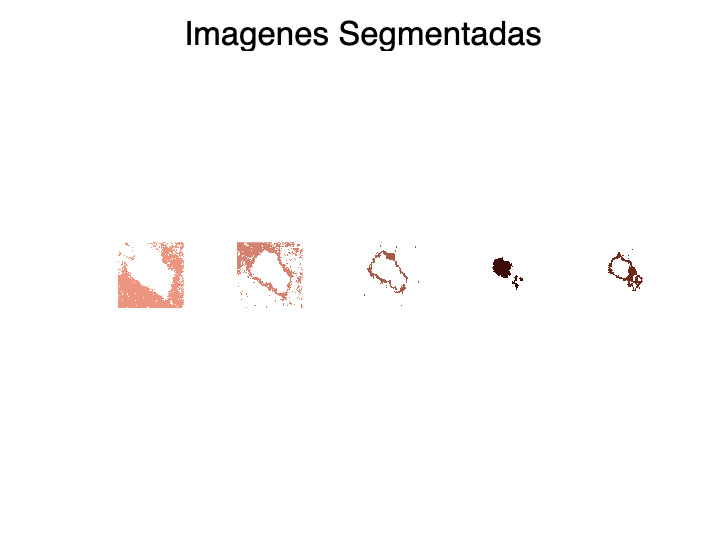


results02 = cell(1, 5);
    
for i = 1:5
    results02{i} = ones(size(originalImage, 1), size(originalImage, 2), 3, 'double');
end

for fila = 1:size(originalImage,1)
    for columna = 1:size(originalImage,2)
        actualValue = cmap2(fila,columna);
        results02{actualValue}(fila,columna, 1) = colors(cmap2(fila,columna),1);
        results02{actualValue}(fila,columna, 2) = colors(cmap2(fila,columna),2);
        results02{actualValue}(fila,columna, 3) = colors(cmap2(fila,columna),3);
    end
end

showMultipleImagesNL('Imagenes Segmentadas',results02);

Función para mostrar en una sola fila una serie de imagenes en una figura, recibe la matriz con las imagenes y el título

function showMultipleImagesNL(figure_title, images)
    m = length(images);
    figure;
    for i = 1:m
        subplot(1, m, i);
        imshow(images{i},[]);
    end
    sgtitle(figure_title); 
end